# Introduction to MATLAB and MATLAB Mobile

The task for this project is to collect some physical data with MATLAB Mobile and do something with it! Using what is taught so far, along with the data, write a program with to analyze the chosen movement. The decision was made to conduct a few sprint trials and analyze the runner's speed.

## MATLAB Mobile

For the project, MATLAB Drive Connector must first be installed following specific instructions on the MathWorks website. Subsequently, the MATLAB Mobile app should be downloaded from the smartphone's app store and accessed using a MathWorks Account. Within the app, under the "Sensors" section, the "Stream to" option should be set to "Log" to enable local data logging, functional with or without network connectivity. The default AutoUpload feature uploads data logs to MATLAB Drive, but this can be adjusted to WiFi-only uploads if required.

The types of sensor data to be collected, such as Acceleration, Magnetic Field, Orientation, Angular Velocity, and Position, are to be selected and activated via toggle switches. Data recording is initiated by pressing the blue START button before starting the activity and concluded by hitting the red STOP button. Each data collection trial should be appropriately named and saved for future analysis. All collected data can be accessed and managed in the “Sensor Logs” section of the app.

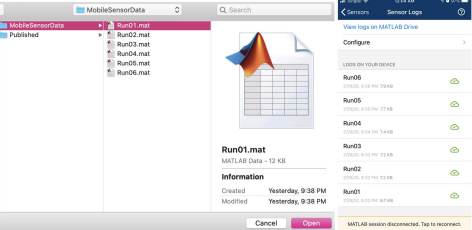

Figure 1: Importing data from MATLAB Mobile to Workspace

## MATLAB Programming

To analyze the data collected using MATLAB Mobile, first ensure connection to the MathWorks Cloud and navigate to the MobileSensorData directory in MATLAB. Import the data by selecting the "Import Data" button in the HOME tab and choosing the desired trial data file. Once imported, select and open the variables for analysis, like "Acceleration." The data will appear in a struct format. Utilize the "dot-operator" to work with specific data elements, such as extracting rows from coordinate data. Maintain a consistent naming system for variables from each trial for efficient organization and analysis. This structured approach aids in conducting comprehensive analyses, including plotting and other advanced data manipulations.

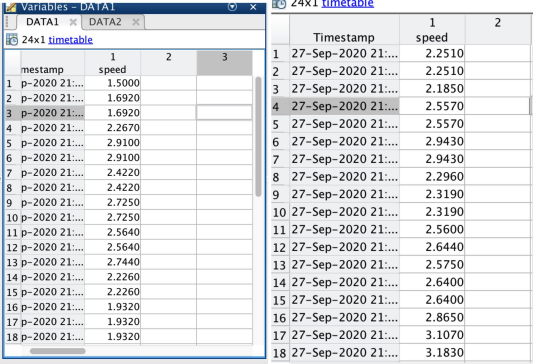

FIgure 2: Sample Data from Sprint Trials

## MATLAB Code

% Collecting Speed Data
Speed_1 = mean(DATA1.speed);
Speed_2 = mean(DATA2.speed);
Speed_3 = mean(DATA3.speed);
Speed_4 = mean(DATA4.speed);
Speed_5 = mean(DATA5.speed);
Speed_6 = mean(DATA6.speed);

% Calculating Average Speed
AvgSpeed = (Speed_1 + Speed_2 + Speed_3 + Speed_4 +  Speed_5 +Speed_6)/6;

% Menu option for displaying average trial speed or input user speed
Choice = menu('Choose a Trial or input your speed! ', 1, 2, 3, 4, 5, 6, 7);

% Switch statements for menu input
switch Choice
    case 1
        disp(Speed_1);
    case 2
        disp(Speed_2);
    case 3
        disp(Speed_3);
    case 4
        disp(Speed_4);
    case 5
        disp(Speed_5);
    case 6
        disp(Speed_6);
    case 7
        Input = input("What is your speed? ");
        % Processing user input
        if Input > 4
            disp('You have a new personal best!')
        else
            disp('Try harder!')
        end
    otherwise
        disp('ERROR!');
end

You have a new personal best!


Collaboration with Paridhi Surana